First Review Project Code

Mathematics For Computing - 4

Group - D8

S Nikhil - CB.SC.U4AIE24351

Dhyan B Krishnan - CB.SC.U4AIE24314

The first code demonstrates image restoration techniques by intentionally blurring the image using a disk-shaped blur kernel (simulating out-of-focus or motion blur), then attempting to recover the original image using two different deconvolution methods: **Wiener deconvolution**, which assumes the blur pattern is known and uses statistical filtering to balance noise and restoration quality, and **blind deconvolution**, which attempts to simultaneously estimate both the original image and the blur pattern through an iterative process.

Essentially showing how MATLAB can undo image degradation when you either know the blur characteristics (non-blind) or need to figure them out from the degraded image itself (blind).

1) Initialization, Image Loading and Display Original Image

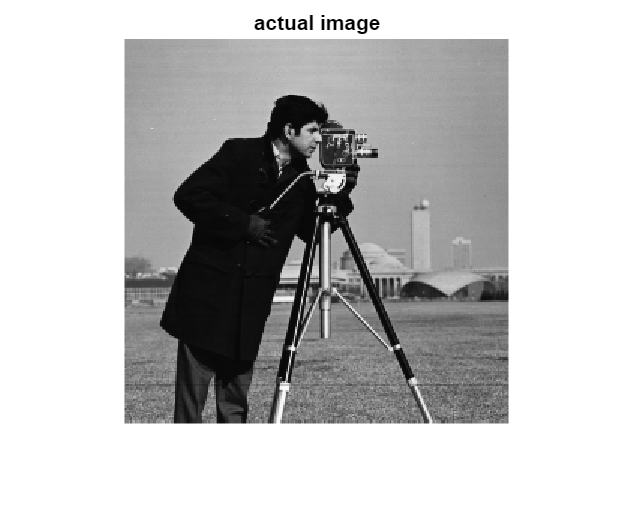

clc; close all;
y=imread('cameraman.tif');
y=im2double(y);
figure,imshow(y); title('actual image')

2) Create Blurred Image using Disk Blur and Display

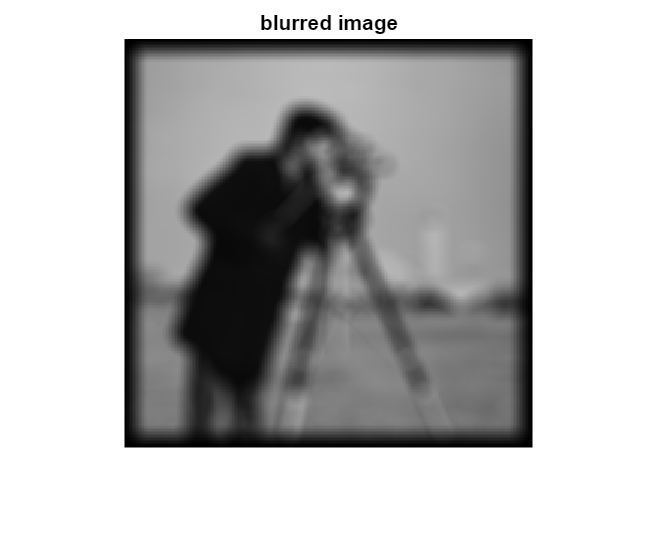

PSF=fspecial('disk',8);
yblur=conv2(y,PSF);
figure,imshow(yblur); title('blurred image')

3) Apply Wiener Deconvolution and Display (Image Restoration)

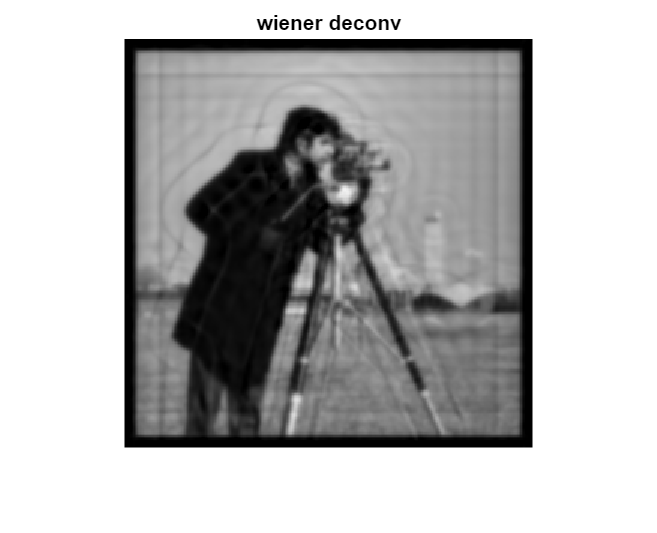

x=deconvwnr(yblur,PSF,0.005);
figure,imshow(x); title('wiener deconv')

4) Apply Blind Convolution and Display (Image Restoration)

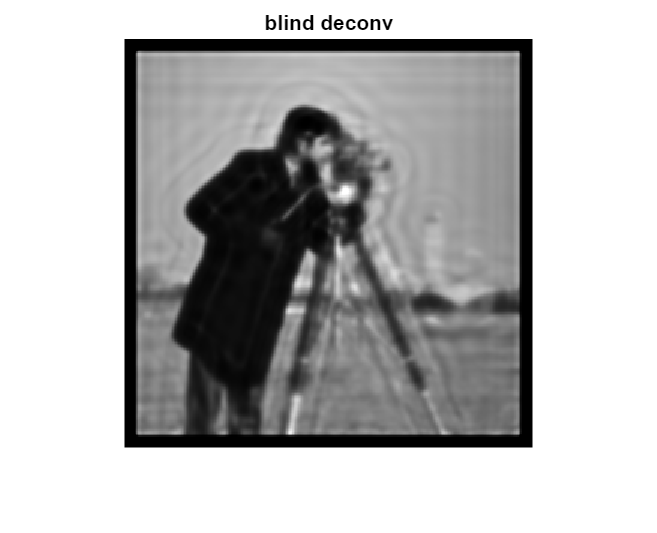

x=deconvblind(yblur,PSF,18);
figure,imshow(x); title('blind deconv')

The second code demonstrates **the problem with naive inverse filtering** by blurring the image with a disk kernel, then adding three progressively higher levels of Gaussian noise (with extremely small variances: 10^-13, 10^-11, and 10^-8), and attempting to restore all versions using direct frequency-domain division (inverse filtering).

The results dramatically show that even imperceptibly tiny amounts of noise get severely amplified during the deconvolution process because dividing by small frequency values in the blur's transfer function magnifies high-frequency noise components, essentially proving why simple inverse filtering fails in real-world scenarios and why more sophisticated regularized methods like Wiener filtering are necessary to handle noise gracefully.

1) Initialization & Image Preparation

clc; close all;
y=im2gray(imread('cameraman.tif'));
y=im2double(y);

2) Create Blurred Image using Disk Blur 

PSF=fspecial('disk',8);
yblur=conv2(y,PSF);

3) Display Original VS Blurred Image

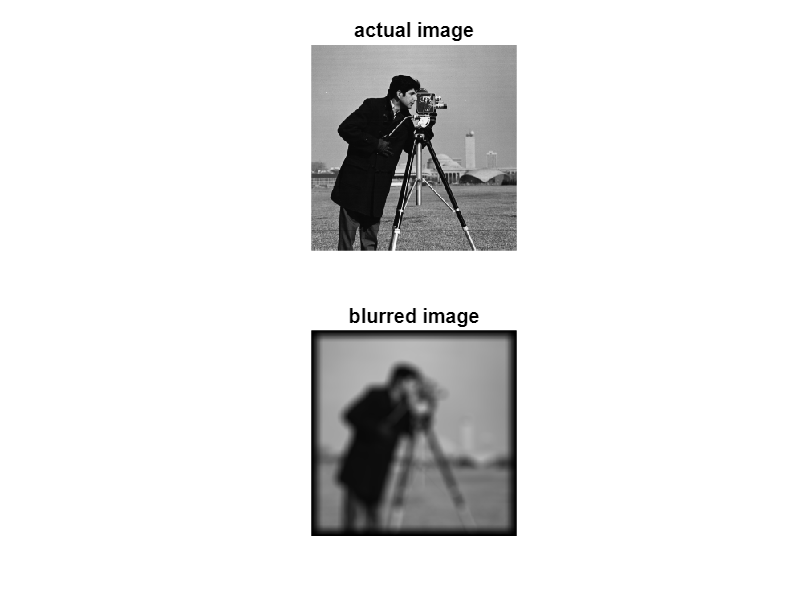

figure();
subplot(2,1,1); imshow(y);title('actual image');
subplot(2,1,2); imshow(yblur); title('blurred image');

4) Add Noise at Different Levels (Variance: 10⁻¹**³, **10⁻¹¹, 10⁻⁸) Low to High

y2BlurredNoisy=imnoise(yblur,'gaussian',0,2e-13);
y3BlurredNoisy=imnoise(yblur,'gaussian',0,2e-11);
y4BlurredNoisy=imnoise(yblur,'gaussian',0,2e-8);

5) Display Noisy Blurred Images

figure();
subplot(2,4,1); imshow(yblur); title('no noise');
subplot(2,4,2); imshow(y2BlurredNoisy); title('Gaussian white noise of variance 10^{-13}')
subplot(2,4,3); imshow(y3BlurredNoisy); title('Gaussian white noise of variance 10^{-11}')
subplot(2,4,4); imshow(y4BlurredNoisy); title('Gaussian white noise of variance 10^{-8}')

6) Frequency Domain Deconvolution (Inverse Filtering)

Y1=fft2(yblur);
Y2=fft2(y2BlurredNoisy);
Y3=fft2(y3BlurredNoisy);
Y4=fft2(y4BlurredNoisy);
newh=zeros(size(yblur));
psfsize=size(PSF);
newh(1: psfsize(1), 1:psfsize(2))=PSF;
H=fft2(newh);
y1deblurred=ifft2(Y1./H);
y2deblurred=ifft2(Y2./H);
y3deblurred=ifft2(Y3./H);
y4deblurred=ifft2(Y4./H);

7) Display Deblurred Images

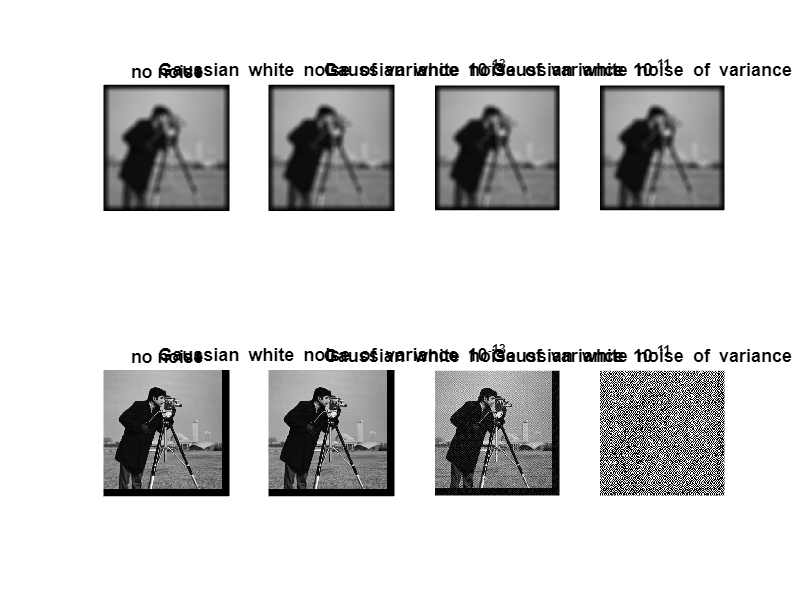

subplot(2,4,5); imshow(y1deblurred); title('no noise')
subplot(2,4,6); imshow(y2deblurred); title('Gaussian white noise of variance 10^{-13}')
subplot(2,4,7); imshow(y3deblurred); title('Gaussian white noise of variance 10^{-11}')
subplot(2,4,8); imshow(y4deblurred); title('Gaussian white noise of variance 10^{-8}')